# 1

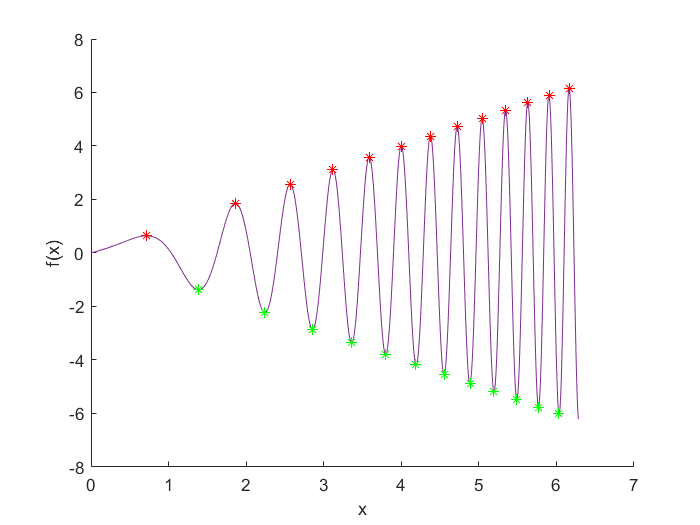

a = 0;
b = 2 * pi;
n = 1000;
f = @(x) abs(x).*sin(2.*(x.^2)+1);
Net = linspace(a,b,n);
FunNet = f(Net);

hold on
plot(Net, FunNet);
xlabel("x");
ylabel("f(x)");

maxMask = islocalmax(FunNet);
minMask = islocalmin(FunNet);

plot(Net(maxMask), FunNet(maxMask), 'r*');
plot(Net(minMask), FunNet(minMask), 'g*');

# 2

n = input('Enter n:');
if ~isprime(n)
    disp('N is not primary');
end

N is not primary


%2.1
X = 1:n;
X = X((mod(X,2) == 1) & (mod(X,7) == 0))

X = 7

%2.2
x = ones(1,n);
y = 2:n+1;
X = y'*x

X =      2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10
    11    11    11    11    11    11    11    11    11    11


%2.3
B = 1:(n+1)*(n+1);
B = reshape(B,[n+1,n+1]);
B = B'

B =      1     2     3     4     5     6     7     8     9    10    11
    12    13    14    15    16    17    18    19    20    21    22
    23    24    25    26    27    28    29    30    31    32    33
    34    35    36    37    38    39    40    41    42    43    44
    45    46    47    48    49    50    51    52    53    54    55
    56    57    58    59    60    61    62    63    64    65    66
    67    68    69    70    71    72    73    74    75    76    77
    78    79    80    81    82    83    84    85    86    87    88
    89    90    91    92    93    94    95    96    97    98    99
   100   101   102   103   104   105   106   107   108   109   110


D = B(:,n:n+1);
c = reshape(B',[1,(n+1) * (n+1)]);

# 3

d = 0.001;
m = 5;
Xnorm = randn(13,7) * sqrt(d) + m

Xnorm =     4.9709    4.9884    5.0415    4.9635    4.9170    5.0421    5.0259
    4.9751    5.0360    5.0403    5.0071    5.0163    4.9993    5.0171
    5.0405    4.9583    4.9982    4.9434    5.0330    4.9966    5.0239
    5.0091    4.9627    4.9533    5.0179    4.9855    4.9753    4.9954
    5.0347    5.0497    5.0424    5.0093    4.9688    5.0350    4.9911
    5.0065    4.9968    4.9949    5.0053    4.9746    4.9982    5.0018
    4.9764    5.0074    4.9620    4.9594    4.9865    5.0310    4.9743
    4.9463    4.9788    5.0688    5.0253    5.0404    5.0276    4.9736
    5.0248    5.0389    5.0180    5.0166    5.0004    5.0225    4.9686
    4.9826    4.9618    4.9308    4.9603    5.0403    5.0120    4.9865



diagonal = diag(Xnorm);
maxdiag = max(diagonal);
mindiag = min(diagonal);
if abs(maxdiag) < abs(mindiag)
    maxabs = mindiag
else 
    maxabs = maxdiag
end

maxabs = 5.0360

prodOfColumns = prod(Xnorm);
sumOfColumns = sum(Xnorm);
relationVect = prodOfColumns ./ sumOfColumns;
maxRelation = max(relationVect)
SortedX = sortrows(Xnorm, 'descend')

# 4

%4.1
n = 6;
A = zeros(2*n+1);
edgeVect = zeros(1,2*n+1);
edgeVect([1 2:2:end-1 end]) = 5;
A(1,:) = edgeVect;
A(:,1) = edgeVect';
A(end,:) = edgeVect;
A(:,end) = edgeVect';
A(n:n+2, n:n+2) = 10;
A(n+1,n+1) = -5

A =      5     5     0     5     0     5     0     5     0     5     0     5     5
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0    10    -5    10     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5


%4.2
A = ones(2*n+1) * 5;
A (1, 3:2:end-2) = 0;
A (2*n+1, 3:2:end-2) = 0;
A (3:2:end-2, 1) = 0;
A (3:2:end-2, 2*n+1) = 0;
A(2:end-1, 2:end-1) = 0;
A(n:n+2, n:n+2) = 10;
A(n+1, n+1) = -5

A =      5     5     0     5     0     5     0     5     0     5     0     5     5
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0    10    -5    10     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5


%4.3
x = ones(1,2*n+1) * 5;
x(3:2:end-2) = 0;
y = zeros(1, 2*n+1);
z = y;
z([1 2*n+1]) = 5;
w = z;
w(n:n+2) = 10;
q = w;
q(n+1) = -5;
q([1 2*n+1]) = 0;
A = x;
for i = 1:(n-2)/2
    A = cat(1,A,z);
    A = cat(1,A,y);
end
A = cat(1,A,w);
A = cat(1,A,q);
A = cat(1,A,w);
for i = 1:(n-2)/2
    A = cat (1,A,y);
    A = cat (1,A,z);
end
A = cat(1,A,x)

A =      5     5     0     5     0     5     0     5     0     5     0     5     5
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0    10    -5    10     0     0     0     0     0
     5     0     0     0     0    10    10    10     0     0     0     0     5
     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     5


# 5

n = 10;
Coord = randi(10,2,n);
A = Coord(1,:)'* Coord(2,:)- Coord(2,:)' * Coord(1,:)

# 6

n = 3;
m = 4;
a = randi([-10, 10], 1, n)

a =      6     6    -7


b = randi([-10, 10], 1, m)

b =      0    -1     3     4


maxdiff = max(max(a) - min(b),max(b) - min(a))

maxdiff = 11

# 7

n = 4;
m = 5;
X = randi (2,n,m) - 1

X =      0     0     1     0     1
     1     1     1     1     1
     0     0     0     0     0
     1     1     0     1     0



[elems, indeces] = min(~X);
indeces

indeces =      2     2     1     2     1


# 8

n = 10;
k = 3;
Coord = randi(10,n,k) - 5

Coord =      5     4     1
     2     3    -2
     3     3    -3
    -2     0     1
     1     0     2
     2    -4     4
     3    -1    -2
    -2     5     1
     3     5    -3
     0     1    -1


G = Coord * Coord';
xiMatr = repmat(diag(G), 1, n);
xjMatr = repmat(diag(G)', n, 1);
DistMatr = sqrt(xiMatr - 2*G + xjMatr)

DistMatr =          0    4.3589    4.5826    8.0623    5.7446    9.0554    6.1644    7.0711    4.5826    6.1644
    4.3589         0    1.4142    5.8310    5.0990    9.2195    4.1231    5.3852    2.4495    3.0000
    4.5826    1.4142         0    7.0711    6.1644    9.9499    4.1231    6.7082    2.0000    4.1231
    8.0623    5.8310    7.0711         0    3.1623    6.4031    5.9161    5.0000    8.1240    3.0000
    5.7446    5.0990    6.1644    3.1623         0    4.5826    4.5826    5.9161    7.3485    3.3166
    9.0554    9.2195    9.9499    6.4031    4.5826         0    6.7823   10.2956   11.4455    7.3485
    6.1644    4.1231    4.1231    5.9161    4.5826    6.7823         0    8.3666    6.0828    3.7417
    7.0711    5.3852    6.7082    5.0000    5.9161   10.2956    8.3666         0    6.4031    4.8990
    4.5826    2.4495    2.0000    8.1240    7.3485   11.4455    6.0828    6.4031         0    5.3852
    6.1644    3.0000    4.1231    3.0000    3.3166    7.3485    3.7417    4.8990

# 9

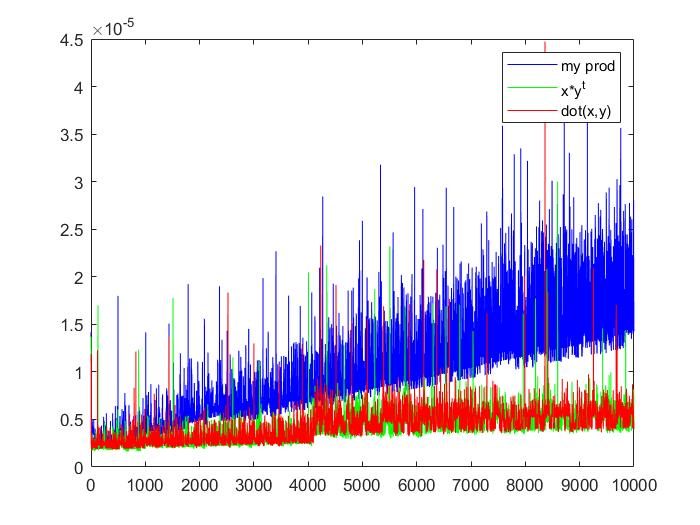

reps = 10000;
tics = 50;
times = zeros(1,reps);
for n = 1:reps
    x = randi(10, 1, n);
    y = randi(10, 1, n);
    tic;
    for i = 1:tics
        prod = my_prod(x,y);
    end
    elapsedTime = toc/tics;
    times(n) = elapsedTime;
end
plot(times,'b');
hold on
for n = 1:reps
    x = randi(10, 1, n);
    y = randi(10, 1, n);
    tic;
    for i = 1:tics
        prod = x*y';
    end
    elapsedTime = toc/tics;
    times(n) = elapsedTime;
end
plot(times,'g');
for n = 1:reps
    x = randi(10, 1, n);
    y = randi(10, 1, n);
    tic;
    for i = 1:tics
        prod = dot(x,y);
    end
    elapsedTime = toc/tics;
    times(n) = elapsedTime;
end
plot(times,'r');
hold off
legend('my prod', 'x*y^t', 'dot(x,y)');

# 10

A = [1 2 3; 4 5 6; 7 8 9];
B = [1 2 3; 7 8 9; 5 6 8];
n = 3;
rowAinB = zeros(n,1);
for i = 1:n
    AinB = ismember(A,B(i,:));
    rowSumAinB = sum(AinB, 2);
    rowAinB = rowAinB + ismember(rowSumAinB, 3);
end
rowAinB

rowAinB =      1
     0
     1


# 11

a = 5;
d = 0.5;
n = 100;
b = 1;
x = randn(1,n) * sqrt(d) + a;
num = length(x(abs(x-a) > b));
prob = num/n

prob = 0.2100

c = d/b^2

c = 0.5000

# 12

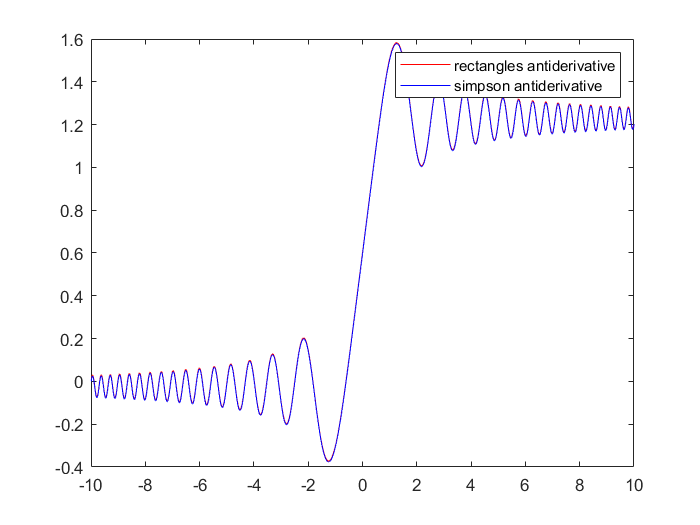

delta = 0.01;
a = -10;
b = 10;
nint(1) = 0;
for i = 2:(b-a)/delta
    x = a:delta:a + i*delta;
    y = cos(x.^2);
    rectUint(i+1) = rectangles(x,y);
    simpUint(i+1) = simpson(x,y);
end
plot(x,rectUint, 'r');
hold on
plot(x,simpUint, 'b');
hold off
legend('rectangles antiderivative', 'simpson antiderivative');

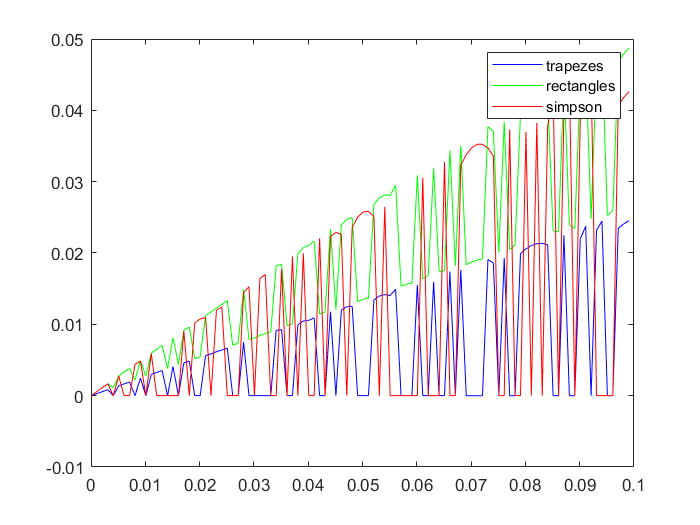


h1 = 0.0001;
h2 = 0.1;
dh = 0.001;

H = h1:dh:h2;
for i = 1:(h2-h1)/dh + 1
    h = H(i);
    xh = a:h:b;
    xh2 = a:h/2:b;
    yh = sin(xh);
    yh2 = sin(xh2);
    deltaIntRect(i) = rectangles(xh, yh) - rectangles(xh2, yh2);
    deltaIntTrap(i) = trapz(xh, yh) - trapz(xh2, yh2);
    deltaIntSim(i) = simpson(xh, yh) - simpson(xh2, yh2);
end

plot(H, deltaIntTrap, 'b');
hold on
plot(H, deltaIntRect, 'g');
plot(H , deltaIntSim, 'r');
hold off
legend('trapezes', 'rectangles', 'simpson');


tic
intrec = rectangles(xh,yh);
toc

Elapsed time is 0.004111 seconds.


tic
intsim = simpson(xh,yh);
toc

Elapsed time is 0.004642 seconds.


# 13

f = @(x) sin(x) .* x;
df = @(x) cos(x) .*x + sin(x);
x0 = 1;
h1 = -8;
h2 = -1;
n = 1000;

H = logspace(h1, h2, n)

H =     0.1000    0.1016    0.1033    0.1050    0.1067    0.1084    0.1102    0.1120    0.1138    0.1156    0.1175    0.1194    0.1214    0.1233    0.1253    0.1274    0.1295    0.1316    0.1337    0.1359    0.1381    0.1403    0.1426    0.1449    0.1473    0.1497    0.1521    0.1546    0.1571    0.1597    0.1623    0.1649    0.1676    0.1703    0.1731    0.1759    0.1788    0.1817    0.1846    0.1876    0.1907    0.1938    0.1969    0.2001    0.2034    0.2067    0.2100    0.2135    0.2169    0.2205


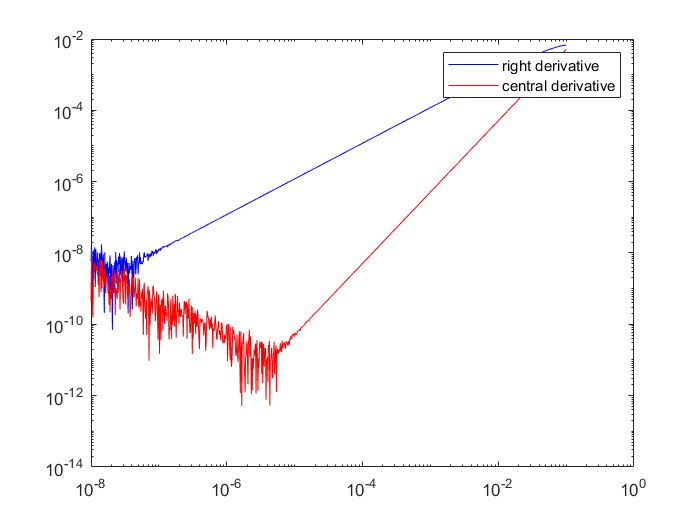

rightdif =@ (h) (f(x0 + h) - f(x0)) ./ h;
centraldif =@ (h) (f(x0 + h) - f(x0 - h)) ./ (2 * h);
deltaCentr = abs(centraldif(H) - df(x0));
deltaRight = abs(rightdif(H) - df(x0));

loglog(H , deltaRight, 'b');
hold on
loglog(H, deltaCentr , 'r');
hold off
legend('right derivative', 'central derivative');